# Here we test the cross dataset predictive capacity of the rs-fMRI signatures

## study 6

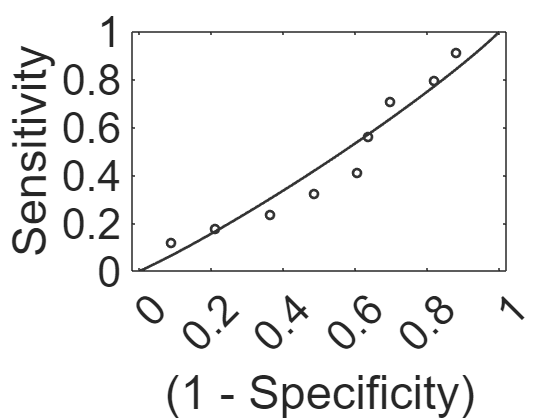

clear, clc
datadir = 'G:\A_arousal_analysis\data';
load(fullfile(datadir, 'A_arousal_connectivity_patterns.mat'))
load(fullfile(datadir, 'FC_UESTC_s6.mat'))

FC = atanh(FC);
FC(isnan(FC)) = 0;
FC(~isfinite(FC)) = 0;
FC = FC(32:end, parcel_idx);
label = [ones(34, 1); -ones(33, 1)];

load(fullfile(datadir, "A_MDD_decoder_study7.mat"), 'weight', 'bias');
pred_label = FC * weight'+bias;
figure;
roc = roc_plot(pred_label, label>0, 'nooutput');

fprintf('\n Study 7 signature predicts study 6: ACC = %.04g%% ± %.04g%%, P = %.02g, AUC = %.02g, d = %.02g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 7 signature predicts study 6: ACC = 53.73% ± 6.091%, P = 0.71, AUC = 0.46, d = -0.17 


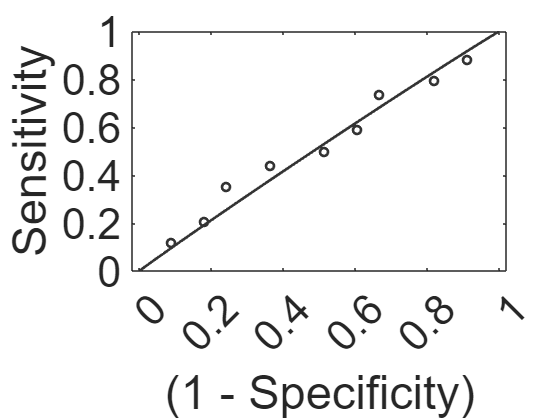


load(fullfile(datadir, "A_MDD_decoder_study8.mat"), 'weight', 'bias');
pred_label = FC * weight'+bias;
figure;
roc = roc_plot(pred_label, label>0, 'nooutput');

fprintf('\n Study 8 signature predicts study 6: ACC = %.04g%% ± %.04g%%, P = %.02g, AUC = %.02g, d = %.02g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 8 signature predicts study 6: ACC = 56.72% ± 6.053%, P = 0.39, AUC = 0.54, d = 0.042 


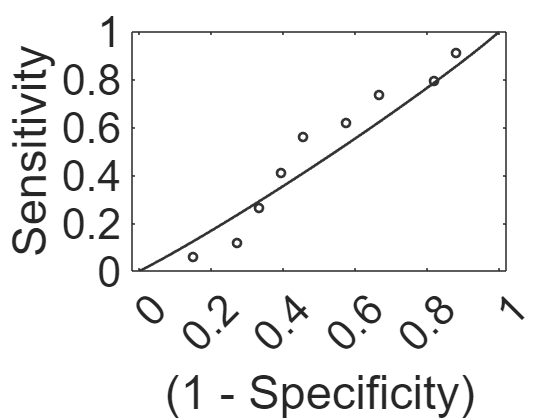


load(fullfile(datadir, "A_MDD_decoder_study9.mat"), 'weight', 'bias');
pred_label = FC * weight'+bias;
figure;
roc = roc_plot(pred_label, label>0, 'nooutput');

fprintf('\n Study 7 signature predicts study 9: ACC = %.04g%% ± %.04g%%, P = %.02g, AUC = %.02g, d = %.02g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 7 signature predicts study 9: ACC = 58.21% ± 6.026%, P = 0.27, AUC = 0.51, d = -0.12 


## study 7

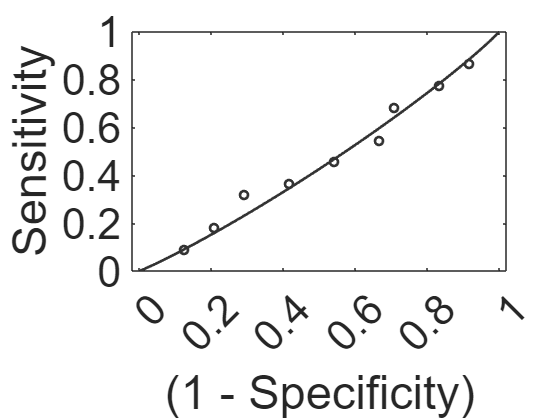

clear, clc
datadir = 'G:\A_arousal_analysis\data';
load(fullfile(datadir, 'A_arousal_connectivity_patterns.mat'))
load(fullfile(datadir, 'FC_Chongqing_s6.mat'))

FC = atanh(FC);
FC(isnan(FC)) = 0;
FC(~isfinite(FC)) = 0;
label = [-ones(24, 1); ones(30, 1)];
included =  patient ~=2;
FC = FC(included, parcel_idx);
label = label(included);

load(fullfile(datadir, "A_MDD_decoder_study6.mat"), 'weight', 'bias');
pred_label = FC * weight'+bias;
figure;
roc = roc_plot(pred_label, label>0, 'nooutput'); 

fprintf('\n Study 6 signature predicts study 7: ACC = %.04g%% ± %.04g%%, P = %.02g, AUC = %.02g, d = %.02g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 6 signature predicts study 7: ACC = 52.17% ± 7.365%, P = 1, AUC = 0.48, d = -0.19 


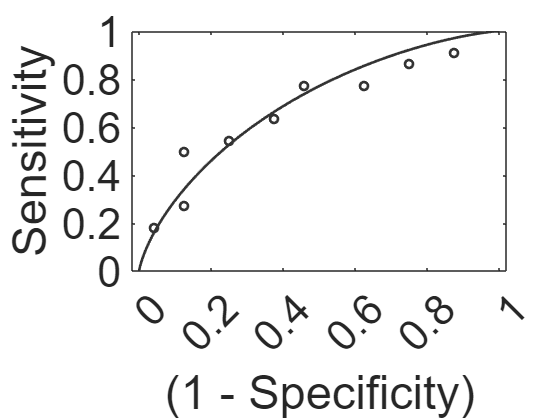


load(fullfile(datadir, "A_MDD_decoder_study8.mat"), 'weight', 'bias');
pred_label = FC * weight'+bias;
figure;
roc = roc_plot(pred_label, label>0, 'nooutput');

fprintf('\n Study 8 signature predicts study 7: ACC = %.04g%% ± %.04g%%, P = %.02g, AUC = %.02g, d = %.02g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 8 signature predicts study 7: ACC = 69.57% ± 6.784%, P = 0.025, AUC = 0.7, d = 0.74 


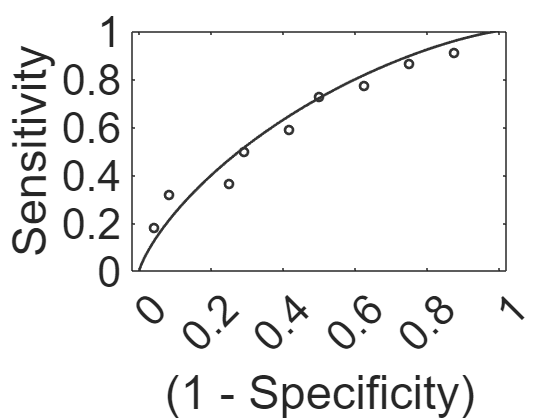


load(fullfile(datadir, "A_MDD_decoder_study9.mat"), 'weight', 'bias');
pred_label = FC * weight'+bias;
figure;
roc = roc_plot(pred_label, label>0, 'nooutput');

fprintf('\n Study 9 signature predicts study 7: ACC = %.04g%% ± %.04g%%, P = %.02g, AUC = %.02g, d = %.02g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 9 signature predicts study 7: ACC = 65.22% ± 7.022%, P = 0.1, AUC = 0.66, d = 0.59 


## study 8

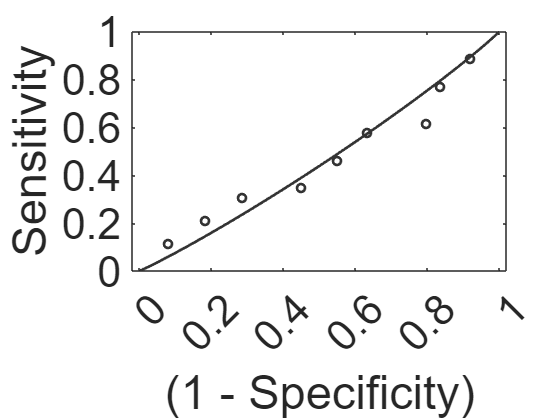

clear, clc
datadir = 'G:\A_arousal_analysis\data';
load(fullfile(datadir, 'A_arousal_connectivity_patterns.mat'))
load(fullfile(datadir, 'FC_Chongqing2_s6.mat'))

FC = atanh(FC);
FC(~isfinite(FC)) = 0;
FC = FC(~excluded, parcel_idx);
label = label(~excluded);
label(label==0) = -1;

load(fullfile(datadir, "A_MDD_decoder_study6.mat"), 'weight', 'bias');
pred_label = FC * weight'+bias;
figure;
roc = roc_plot(pred_label, label>0, 'nooutput'); 

fprintf('\n Study 6 signature predicts study 8: ACC = %.04g%% ± %.04g%%, P = %.02g, AUC = %.02g, d = %.02g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 6 signature predicts study 8: ACC = 53.47% ± 4.963%, P = 0.77, AUC = 0.46, d = -0.16 


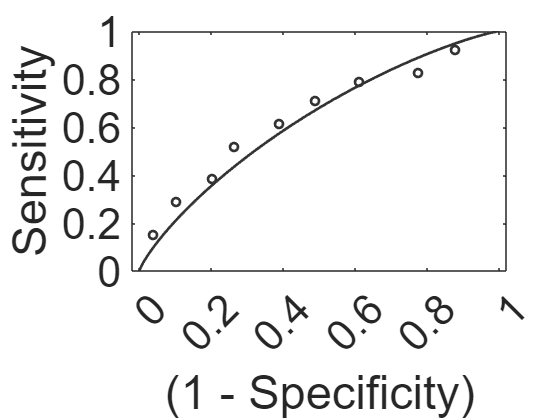


load(fullfile(datadir, "A_MDD_decoder_study7.mat"), 'weight', 'bias');
pred_label = FC * weight'+bias;
figure;
roc = roc_plot(pred_label, label>0, 'nooutput'); 

fprintf('\n Study 7 signature predicts study 8: ACC = %.04g%% ± %.04g%%, P = %.02g, AUC = %.02g, d = %.02g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 7 signature predicts study 8: ACC = 64.36% ± 4.766%, P = 0.012, AUC = 0.66, d = 0.47 


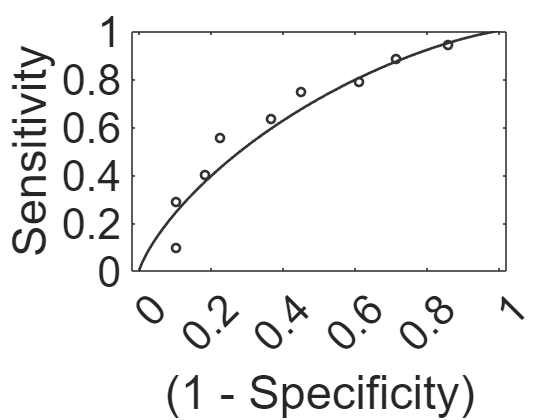


load(fullfile(datadir, "A_MDD_decoder_study9.mat"), 'weight', 'bias');
pred_label = FC * weight'+bias;
figure;
roc = roc_plot(pred_label, label>0, 'nooutput');

fprintf('\n Study 9 signature predicts study 8: ACC = %.04g%% ± %.04g%%, P = %.02g, AUC = %.02g, d = %.02g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 9 signature predicts study 8: ACC = 68.32% ± 4.629%, P = 0.00089, AUC = 0.69, d = 0.58 


## study 9

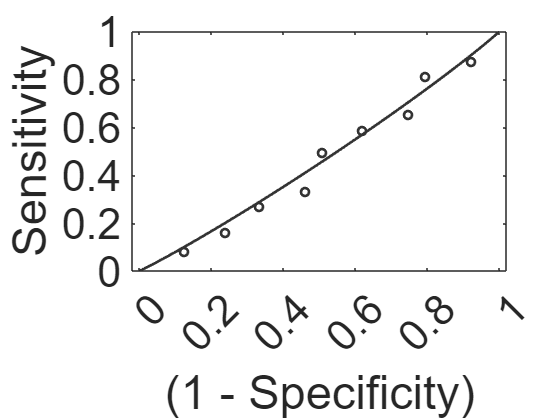

clear, clc
datadir = 'G:\A_arousal_analysis\data';
load(fullfile(datadir, 'A_arousal_connectivity_patterns.mat'))
load(fullfile(datadir, 'FC_BANDA_s6.mat'))

FC_run1 = atanh(FC_run1);
FC_run1(FC_run1==0) = NaN;
FC_run1(~isfinite(FC_run1)) = NaN;
FC_run1(outlier_run1,:) = NaN; % num of spikes > num of timepoints * 0.25
FC_run2 = atanh(FC_run2);
FC_run2(FC_run2==0) = NaN;
FC_run2(~isfinite(FC_run2)) = NaN;
FC_run2(outlier_run2,:) = NaN; % num of spikes > num of timepoints * 0.25

FC = [];
FC(:, :, 1) = FC_run1;
FC(:, :, 2) = FC_run2;
clear FC_*
FC = mean(FC, 3, 'omitnan');
FC = FC(:, parcel_idx);
excluded_fmri = outlier_run1 & outlier_run2;

T = readtable(fullfile(datadir, 'ndar_subject01.csv'),'VariableNamingRule', 'preserve', 'TreatAsEmpty', 'n/a');
control = false(206,1);
depression = false(206,1);
anxiety = false(206,1);
for i = 1:206
    idx = strcmp(T.src_subject_id, subIDs{i}(5:end)) & strcmp(T.visit,'T1');
    if sum(idx) == 1
    if strcmp(T.phenotype(idx),'Control')
        control(i) = true;
    elseif strcmp(T.phenotype(idx),'Depression')
        depression(i) = true;
    elseif strcmp(T.phenotype(idx),'Anxiety')
        anxiety(i) = true;
    end
    end
end

FC_depr = FC(depression & ~excluded_fmri,:);
FC_con = FC(control & ~excluded_fmri,:);
clear FC
ndepr = size(FC_depr, 1);
ncon = size(FC_con, 1);
label = [ones(ndepr,1); -ones(ncon, 1)];
FC = [FC_depr; FC_con];

load(fullfile(datadir, "A_MDD_decoder_study6.mat"), 'weight', 'bias');
pred_label = FC * weight'+bias;
figure;
roc = roc_plot(pred_label, label>0, 'nooutput'); 

fprintf('\n Study 6 signature predicts study 9: ACC = %.04g%% ± %.04g%%, P = %.02g, AUC = %.02g, d = %.02g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 6 signature predicts study 9: ACC = 52.38% ± 4.449%, P = 0.66, AUC = 0.46, d = -0.13 


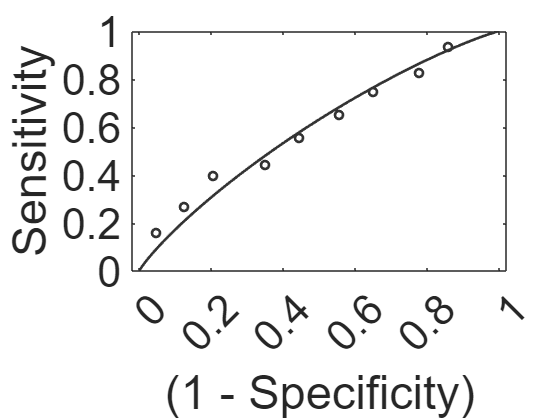


load(fullfile(datadir, "A_MDD_decoder_study7.mat"), 'weight', 'bias');
pred_label = FC * weight'+bias;
figure;
roc = roc_plot(pred_label, label>0, 'nooutput');

fprintf('\n Study 7 signature predicts study 9: ACC = %.04g%% ± %.04g%%, P = %.02g, AUC = %.02g, d = %.02g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 7 signature predicts study 9: ACC = 59.52% ± 4.373%, P = 0.04, AUC = 0.6, d = 0.34 


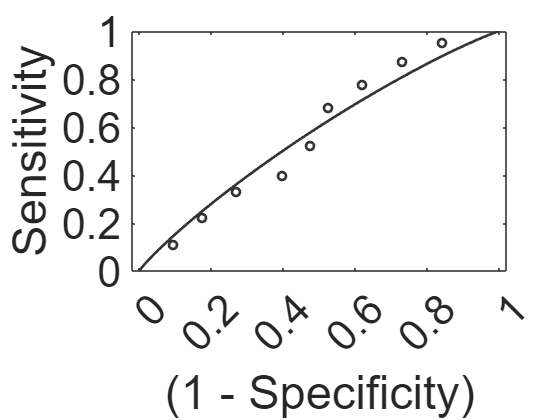


load(fullfile(datadir, "A_MDD_decoder_study8.mat"), 'weight', 'bias');
pred_label = FC * weight'+bias;
figure;
roc = roc_plot(pred_label, label>0, 'nooutput');

fprintf('\n Study 8 signature predicts study 9: ACC = %.04g%% ± %.04g%%, P = %.02g, AUC = %.02g, d = %.02g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 8 signature predicts study 9: ACC = 58.73% ± 4.386%, P = 0.061, AUC = 0.57, d = 0.26 
